
ncfile = '../data/20241015a_vehicle_vessel1_REG_INTERP_TimeSeries.nc';

x = ncread(ncfile,'tlsc_xymean');
x = x(:);

t = ncread(ncfile,'t');
t = t(:);

Fs = 2;


[cfs,f,coi] = cwt(x,Fs,'TimeBandwidth',15,'FrequencyLimits', [0.007, 0.1]);

amp = abs(cfs);

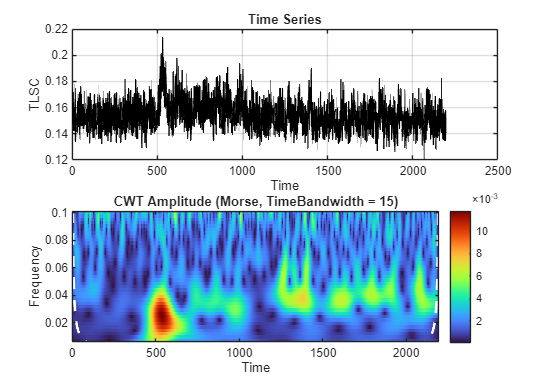

%% Plot
figure('Color','w','Position',[100 100 1000 700])

% Time series
subplot(2,1,1)
plot(t,x,'k','LineWidth',1)
xlabel('Time')
ylabel('TLSC')
title('Time Series')
grid on

% Scalogram
subplot(2,1,2)

imagesc(t,f,amp)
axis xy
hold on

% Plot COI
plot(t,coi,'w--','LineWidth',2)

xlabel('Time')
ylabel('Frequency')
title('CWT Amplitude (Morse, TimeBandwidth = 15)')
colormap(turbo)
colorbar


% Optional: log-frequency axis
% set(gca,'YScale','log')